# M17 Physical Layer 

fred harris

Abraxas3d

## Physical Layer Summary from M17 Specification

Specification can be found at: [https://spec.m17project.org/](https://spec.m17project.org/)

M17 Protocol is 4FSK modulation with a deviation index of 0.33. Channels width is 9-kHz. Channel spacing is 12.5 kHz.

f_sym = 4800 Sym/sec, (2-bits/symbol)

Bit 1   Bit 0    Symbol   4FSK Deviation  

     0       1        +3        +2.4 kHz

     0       0        +1        +0.8 kHz

     1       0        -1        -0.8 kHz

     1       1        -3        -2.4 kHz

   1 0    1 1    0 1    00    -1  -3  +3  +1

Preamable is 40 msec of alternating -3 +3 forms a 2.4 kHz Tone (?)

T_sym = 1/(4.8 kHz Symbol Rate) = 0.208333333 msec

40 msec = 192 symbols

## IQ Modulation

If you need a tutorial about IQ modulation, then an excellent one is here:

https://www.youtube.com/watch?v=h_7d-m1ehoY

## Shaping Filter

% hh=sqrt_nyq_y2(f_smpl,alpha,n_sym,flg_plot) 

% hh=sqrt_nyq_y2(2,0.5,1,1) 

% sqrt-nyq filter, alpha=0.5,12-samples/symbol, 

There is a 6-symbol delay from start to center of filter.

There is a 12-sample delay from start to center of filter.

Filter coefficients are normalized to unity amplitude for modulator

% n_sym=6;

% f_smpl=4;

% alpha=0.5;

% flg_plot=1;

Why do we use shaping filters? To use minimum bandwidth while eliminating inter-symbol interference.

An excellent tutorial can be found here:

[https://www.youtube.com/watch?v=NGzVJSLm0Kc](https://www.youtube.com/watch?v=NGzVJSLm0Kc)

## Nyquist Filter Generation


  hh1=[-0.000118332920848  -0.000404545939760  -0.000292866621779 ...
        0.000091338500384   0.000160271905750  -0.000180687278526 ...
        0.000112155146031   0.002100577618127   0.004513294881905 ...
        0.003177593265155  -0.005219794595151  -0.017054093919535 ...
       -0.020166273315378  -0.002323788670075   0.033753020454632 ...
        0.062349436194728   0.047122921738875  -0.027558286910012 ...
       -0.127772793564709  -0.171987720904940  -0.074524812539715 ...
        0.191489840665154   0.556094419953446   0.873915964233476 ...
        1.000000000000000   0.873915964233476   0.556094419953446 ...
        0.191489840665154  -0.074524812539715  -0.171987720904940 ...
       -0.127772793564709  -0.027558286910012   0.047122921738875 ...
        0.062349436194728   0.033753020454632  -0.002323788670075 ...
       -0.020166273315378  -0.017054093919535  -0.005219794595151 ...
        0.003177593265155   0.004513294881905   0.002100577618127 ...
        0.000112155146031  -0.000180687278526   0.000160271905750 ...
        0.000091338500384  -0.000292866621779  -0.000404545939760 ...
       -0.000118332920848];
   
N=length(hh1)

N = 49

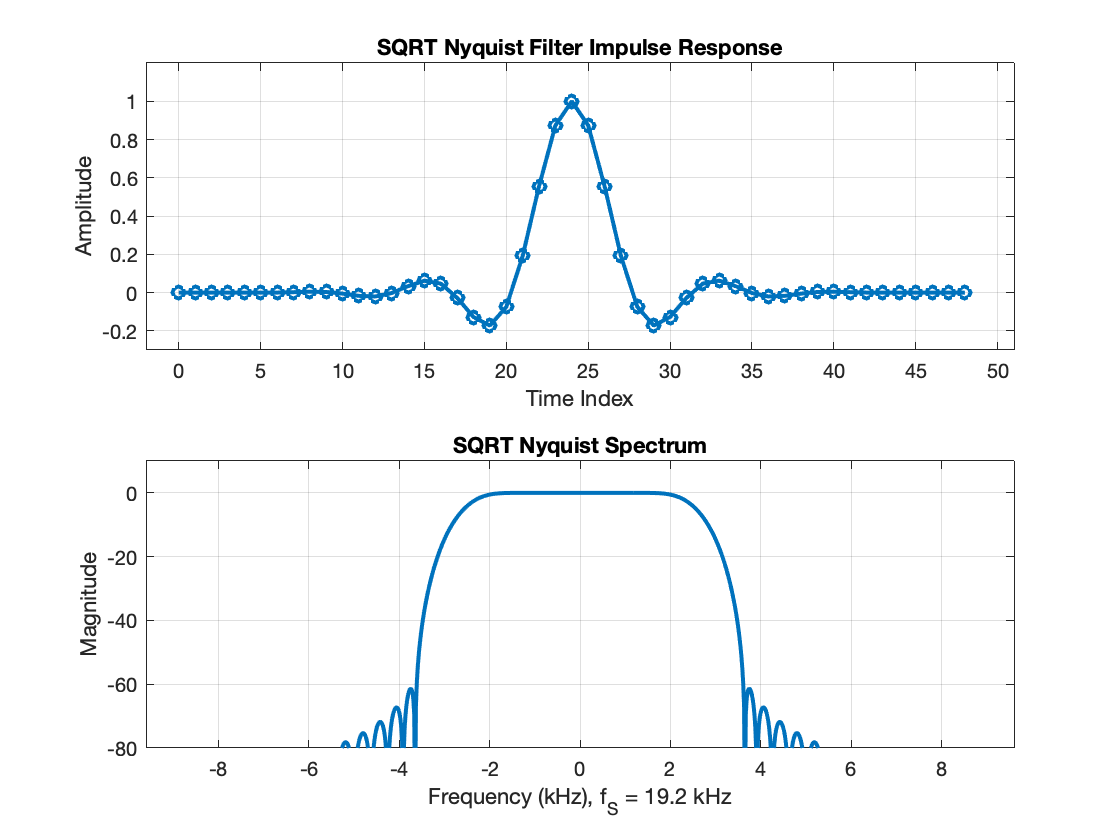

f_smpl=19.2;
figure(6)
subplot(2,1,1)
plot(0:N-1,hh1,'-o','linewidth',2)
grid on
axis([-2 N+2 -0.3 1.2])
title('SQRT Nyquist Filter Impulse Response')
xlabel('Time Index')
ylabel('Amplitude')

subplot(2,1,2)
plot((-0.5:1/1000:0.5-1/1000)*f_smpl,fftshift(20*log10(abs(fft(hh1/sum(hh1),1000)))),'linewidth',2)
grid on
axis([-f_smpl/2 f_smpl/2 -80 10])
title('SQRT Nyquist Spectrum')
xlabel('Frequency (kHz), f_S = 19.2 kHz')
ylabel('Magnitude')

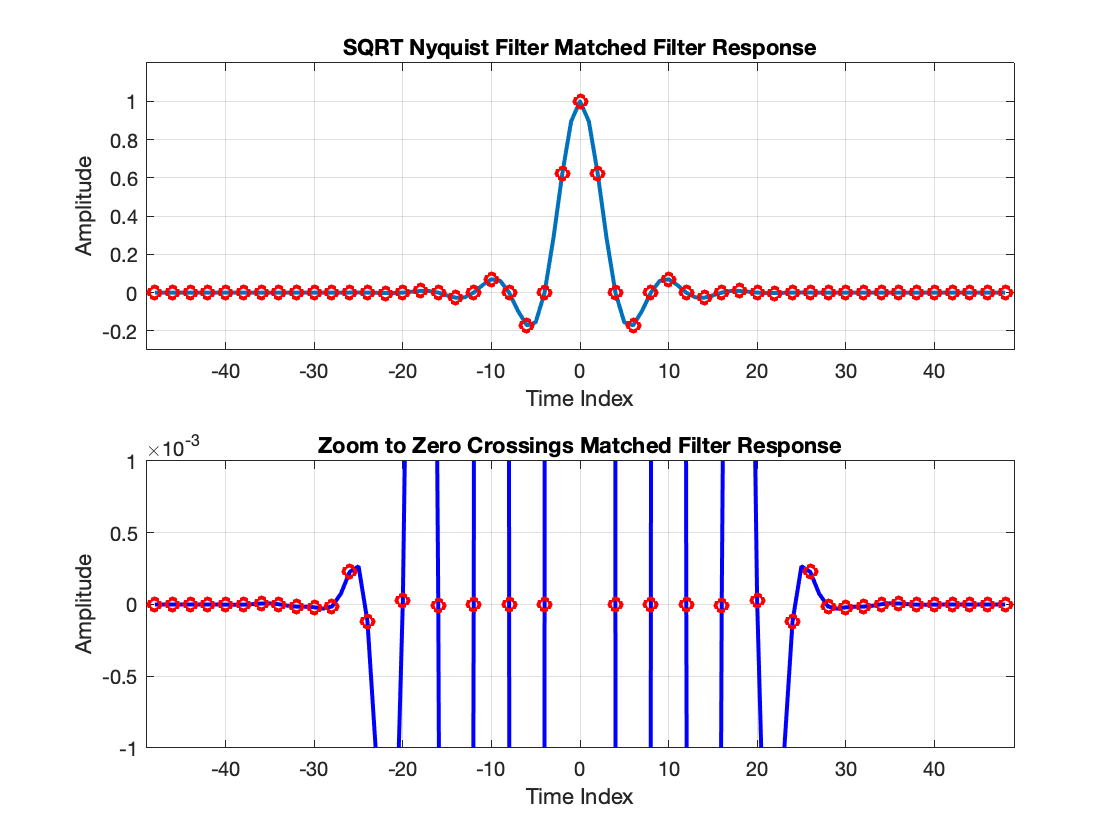


figure(7)
hh2=conv(hh1,hh1)/(hh1*hh1');
subplot(2,1,1)
plot(-(N-1):(N-1),hh2,'linewidth',2)
hold on
plot(-(N-1):2:(N-1),hh2(1:2:2*N),'ro','linewidth',2)
hold off
grid on
axis([-N N -0.3 1.2])
title('SQRT Nyquist Filter Matched Filter Response')
xlabel('Time Index')
ylabel('Amplitude')

hh2=conv(hh1,hh1)/(hh1*hh1');
subplot(2,1,2)
plot(-(N-1):(N-1),hh2,'b','linewidth',2)
hold on
plot(-(N-1):2:(N-1),hh2(1:2:2*N),'ro','linewidth',2)
hold off
grid on
axis([-N N -0.001 0.001])
title('Zoom to Zero Crossings Matched Filter Response')
xlabel('Time Index')
ylabel('Amplitude')

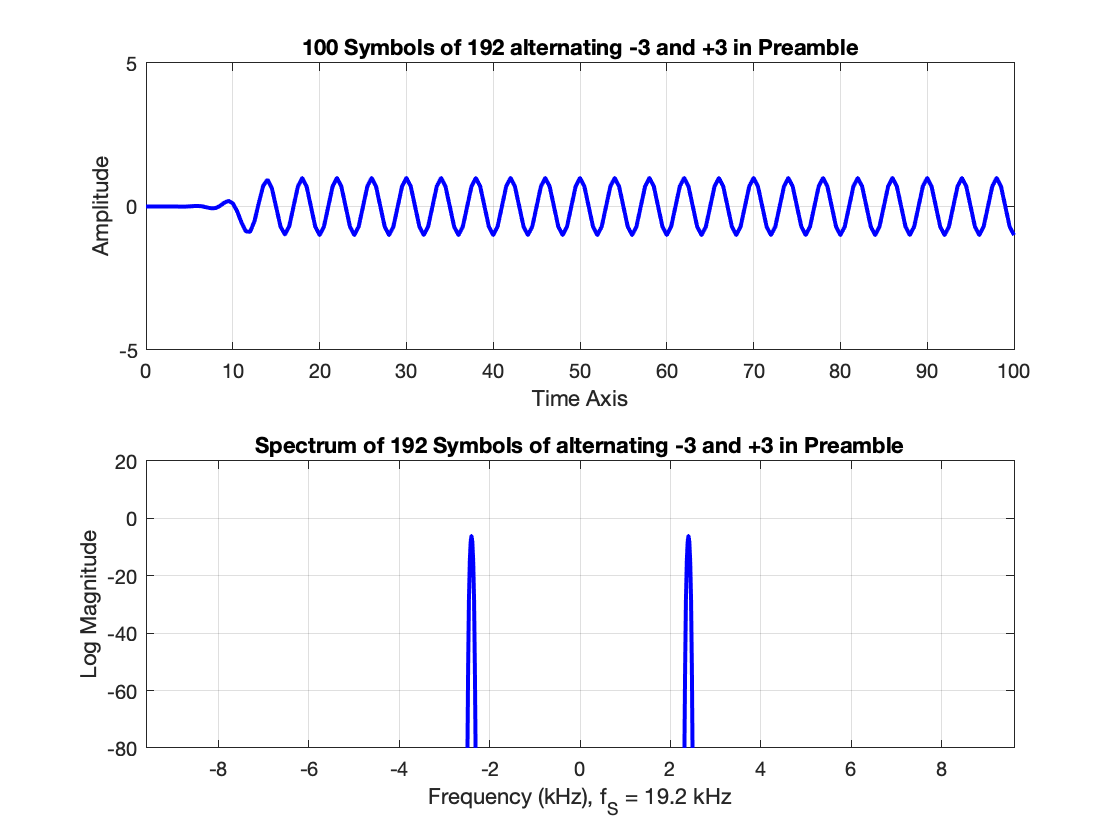


hh1=[hh1 0 0 0]; 

% preamble 192 symbols of alternating -3 +3

y1=zeros(1,192/2);
m=1;
for n=1:192/2
        y1(m)=-3;
        y1(m+1)=+3;
    m=m+2;
end
y1=y1/3;
reg=zeros(1,13);
m=1;
for n=1:192
    reg=[y1(n) reg(1:12)];
    y2(m)=reg*hh1(1:4:52)';
    y2(m+1)=reg*hh1(2:4:52)';
    y2(m+2)=reg*hh1(3:4:52)';
    y2(m+3)=reg*hh1(4:4:52)';    
    m=m+4;
end
y2=y2/1.3;
% y2 has 768 samples
figure(8)
subplot(2,1,1)
plot(0:0.5:100,y2(1:201),'b','linewidth',2)
grid on
axis([0 100 -5 5])
title('100 Symbols of 192 alternating -3 and +3 in Preamble')
xlabel('Time Axis')
ylabel('Amplitude')

ww=kaiser(760,10)';
ww=ww/sum(ww);

subplot(2,1,2)
plot((-0.5:1/1024:0.5-1/1024)*19.2,fftshift(20*log10(abs(fft(y2(9:768).*ww,1024)))),'b','linewidth',2)
grid on
axis([-9.6 9.6 -80 20])
title('Spectrum of 192 Symbols of alternating -3 and +3 in Preamble')
xlabel('Frequency (kHz), f_S = 19.2 kHz')
ylabel('Log Magnitude')

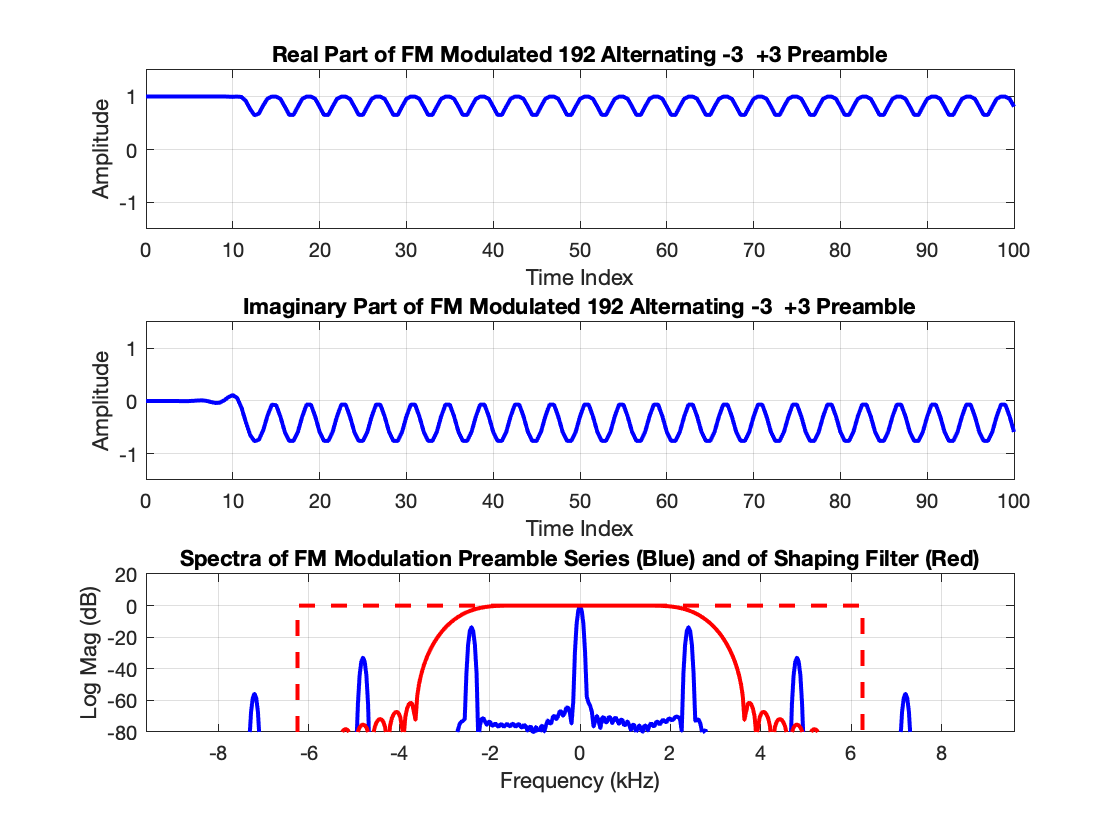


% preamble FM modulator

% FM Modulator

y4=filter(1,[1 -1],y2);
%y5=exp(j*2*pi*y4*scl(k));
y5=exp(j*y4*0.33);

figure(9)
subplot(3,1,1)
plot(0:0.5:100,real(y5(1:201)),'b','linewidth',2)
grid on
axis([0 100 -1.5 1.5])
title('Real Part of FM Modulated 192 Alternating -3  +3 Preamble')
xlabel('Time Index')
ylabel('Amplitude')

subplot(3,1,2)
plot(0:0.5:100,imag(y5(1:201)),'b','linewidth',2)
grid on
axis([0 100 -1.5 1.5])
title('Imaginary Part of FM Modulated 192 Alternating -3  +3 Preamble')
xlabel('Time Index')
ylabel('Amplitude')

subplot(3,1,3)
ww=kaiser(380,8)';
ww=1*ww/sum(ww);
plot((-0.5:1/512:0.5-1/512)*19.2,fftshift(20*log10(abs(fft(y5(5:384).*ww,512)))),'b','linewidth',2)
hold on
plot((-0.5:1/512:0.5-1/512)*19.2,fftshift(20*log10(abs(fft(hh1/sum(hh1),512)))),'r','linewidth',2)
plot([-6.25 -6.25 6.25 6.25],[-80 0 0 -80],'--r','linewidth',2)
hold off
grid on
axis([-9.6 9.6 -80 20])
title('Spectra of FM Modulation Preamble Series (Blue) and of Shaping Filter (Red)')
xlabel('Frequency (kHz)')
ylabel('Log Mag (dB)')

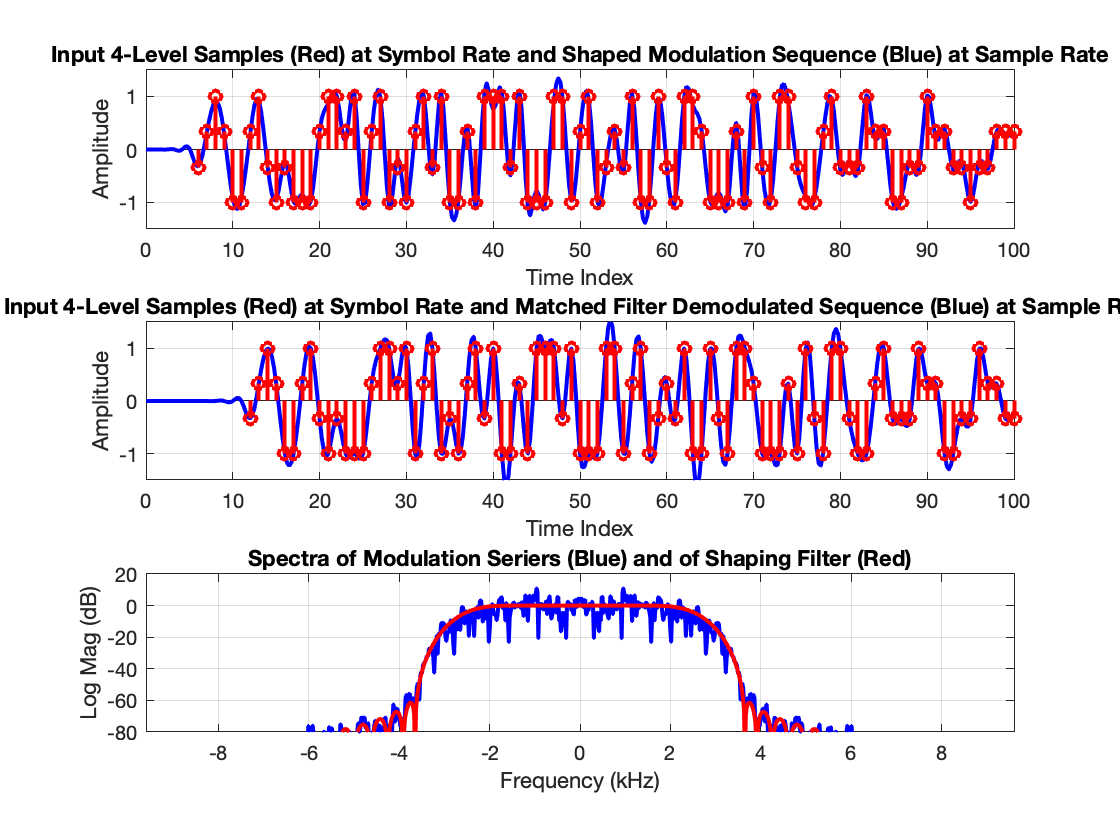


% 4-FSK modulator
N_bits=1000;   % N_bits an even number

x0=floor(2*rand(1,N_bits));

x1=zeros(1,N_bits/2);
m=1;
for n=1:2:N_bits
    if x0(n)==0 & x0(n+1)==1
        x1(m)=+3;
    elseif x0(n)==0 & x0(n+1)==0
        x1(m)=+1;
    elseif x0(n)==1 & x0(n+1)==0
        x1(m)=-1;
    elseif x0(n)==1 & x0(n+1)==1
        x1(m)=-3;
    end
    m=m+1;
end
x1=x1/3;
reg=zeros(1,13);
m=1;
for n=1:N_bits/2
    reg=[x1(n) reg(1:12)];
    x2(m)=reg*hh1(1:4:52)';
    x2(m+1)=reg*hh1(2:4:52)';
    x2(m+2)=reg*hh1(3:4:52)';
    x2(m+3)=reg*hh1(4:4:52)';    
    m=m+4;
end

x3=filter(hh1/(hh1*hh1'),1,x2);
figure(10)
subplot(3,1,1)
plot(0:0.25:100,x2(1:401),'b','linewidth',2)
hold on
stem((0:1:200)+6,x1(1:1:201),'r','linewidth',2)
hold off
grid on
axis([0 100 -1.5 1.5])
title('Input 4-Level Samples (Red) at Symbol Rate and Shaped Modulation Sequence (Blue) at Sample Rate')
xlabel('Time Index')
ylabel('Amplitude')

subplot(3,1,2)
plot(0:0.25:100,x3(1:401),'b','linewidth',2)
hold on
stem((0:1:200)+12,x1(1:1:201),'r','linewidth',2)
hold off
grid on
axis([0 100 -1.5 1.5])
title('Input 4-Level Samples (Red) at Symbol Rate and Matched Filter Demodulated Sequence (Blue) at Sample Rate')
xlabel('Time Index')
ylabel('Amplitude')

subplot(3,1,3)
ww=kaiser(N_bits,8)';
ww=20*ww/sum(ww);
plot((-0.5:1/N_bits:0.5-1/N_bits)*19.2,fftshift(20*log10(abs(fft(x2(1:N_bits).*ww)))),'b','linewidth',2)
hold on
plot((-0.5:1/N_bits:0.5-1/N_bits)*19.2,fftshift(20*log10(abs(fft(hh1/sum(hh1),N_bits)))),'r','linewidth',2)
hold off
grid on
axis([-9.6 9.6 -80 20])
title('Spectra of Modulation Seriers (Blue) and of Shaping Filter (Red)')
xlabel('Frequency (kHz)')
ylabel('Log Mag (dB)')



% FM Modulator
x4=filter(1,[1 -1],x2);
max(x2)

ans = 1.4127

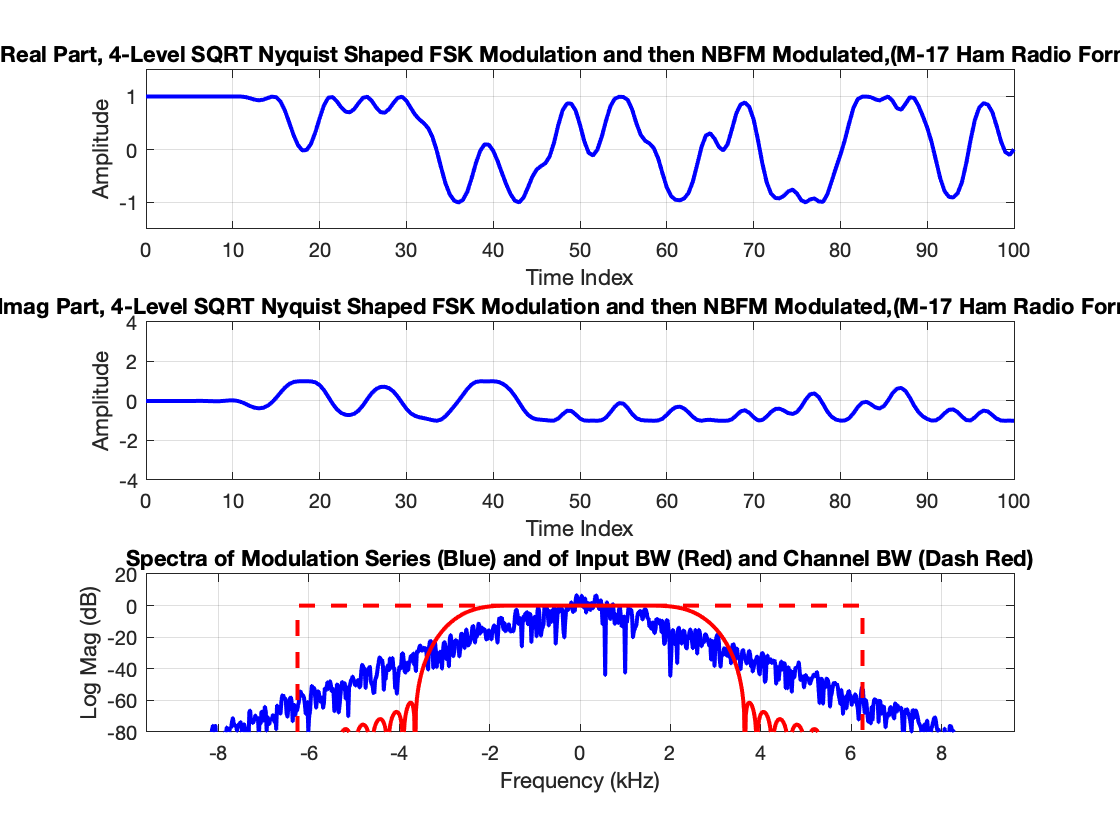

%x5=exp(j*2*pi*x4*0.12899);
x5=exp(j*x4*0.33);

figure(11)
subplot(3,1,1)
plot(0:0.5:100,real(x5(1:201)),'b','linewidth',2)
grid on
axis([0 100 -1.5 1.5])
title('Real Part, 4-Level SQRT Nyquist Shaped FSK Modulation and then NBFM Modulated,(M-17 Ham Radio Format)')
xlabel('Time Index')
ylabel('Amplitude')

subplot(3,1,2)
plot(0:0.5:100,imag(x5(1:201)),'b','linewidth',2)
grid on
axis([0 100 -4 4])
title('Imag Part, 4-Level SQRT Nyquist Shaped FSK Modulation and then NBFM Modulated,(M-17 Ham Radio Format)')
xlabel('Time Index')
ylabel('Amplitude')

subplot(3,1,3)
ww=kaiser(N_bits,8)';
ww=8*ww/sum(ww);
plot((-0.5:1/N_bits:0.5-1/N_bits)*19.2,fftshift(20*log10(abs(fft(x5(1:N_bits).*ww)))),'b','linewidth',2)
hold on
plot((-0.5:1/N_bits:0.5-1/N_bits)*19.2,fftshift(20*log10(abs(fft(hh1/sum(hh1),N_bits)))),'r','linewidth',2)
plot([-6.25 -6.25 6.25 6.25],[-80 0 0 -80],'--r','linewidth',2)
hold off
grid on
axis([-9.6 9.6 -80 20])
title('Spectra of Modulation Series (Blue) and of Input BW (Red) and Channel BW (Dash Red)')
xlabel('Frequency (kHz)')
ylabel('Log Mag (dB)')

## Scratch Pad

N=length(hh1)

N = 52

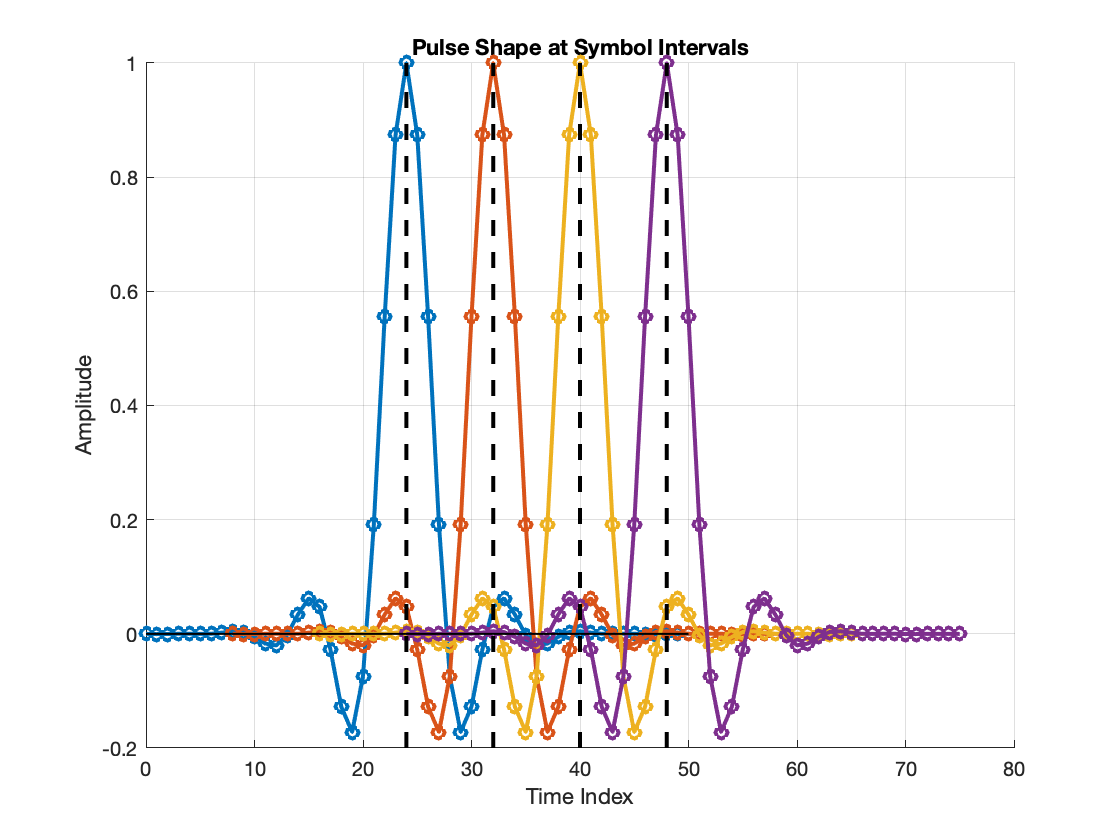

f_smpl=19.2;
figure(20)
%subplot(2,1,1)
% plot(0:N-1,hh1,'-o','linewidth',2)
% hold on
% plot(4:N+3,hh1,'-o','linewidth',2)
% plot(7:N+6,hh1,'-o','linewidth',2)
% plot(10:N+9,hh1,'-o','linewidth',2)


% hh2
% p1 = hh2(1:N-1)
% p2 = [0 0 0 hh2(4:N-1)]
% p3 = p1 .* p2
% plot(p3, '-o', 'linewidth',2)


hold on
plot(0:N-1,hh1,'-o','linewidth',2)
plot(8:N+7,hh1,'-o','linewidth',2)
plot(16:N+15,hh1,'-o','linewidth',2)
plot(24:N+23,hh1,'-o','linewidth',2)




% Draw A Red Vertical Line At ‘x=24’
plot([1 1]*24, ylim, '--k','linewidth',2) 
% Draw A Red Vertical Line At ‘x=24+8’
plot([1 1]*32, ylim, '--k','linewidth',2) 
% Draw A Red Vertical Line At ‘x=24+16’
plot([1 1]*40, ylim, '--k','linewidth',2) 
% Draw A Red Vertical Line At ‘x=24+24’
plot([1 1]*48, ylim, '--k','linewidth',2) 


% Draw A Horizontal Marker At 'y=0'
horizontal_marker = 0;
line([0,50],[horizontal_marker,horizontal_marker],'linewidth',1, 'color', 'black')

hold off
grid on
%axis([-2 N+2 -0.3 1.2])
title('Pulse Shape at Symbol Intervals')
xlabel('Time Index')
ylabel('Amplitude')


%xline(25,'-','Center') % in 2018b and later

% xlim([40 65])
% ylim([-0.220 0.253])
